# АПМ

# Лабораторная работа 1 

***Вариант 6***

## Загружаем модель

clc;cla;clear;close all;
mdl = "Lab1_var6";
load_system("models/"+mdl);


## Запуск при значениях по умолчанию

Kp_def = 0.1;
Ki_def = 12;
Kd_def = 0.10325;

simIn = Simulink.SimulationInput(mdl);
simIn = setVariable(simIn,"Kp", Kp_def);
simIn = setVariable(simIn,"Ki", Ki_def);
simIn = setVariable(simIn,"Kd", Kd_def);
out = sim(simIn);

figure;
plot(out.logsout.getElement("out").Values,'DisplayName',['Curve #' num2str(i)]);
grid on;    

## Перебор Kp

n_of_each = 5;
Kp = logspace(-2,2,n_of_each);
Ki = logspace(-3,1,n_of_each);
Kd = logspace(-3,0,n_of_each);
numOfInp = numel(Kp)*numel(Ki)*numel(Kd);
simIn(1:numOfInp) = Simulink.SimulationInput(mdl);
counter = 1;
simIn(1:numOfInp) = simIn(1:numOfInp).setModelParameter("StopTime", "1");
for i = 1:numel(Kp)
    for j = 1:numel(Ki)
        for k = 1:numel(Kd)
            simIn(counter) = simIn(counter).setVariable('Kp', Kp(i));
            simIn(counter) = simIn(counter).setVariable('Ki', Ki(j));
            simIn(counter) = simIn(counter).setVariable('Kd', Kd(k));
            counter = counter + 1;
        end
    end
end

out = parsim(simIn);

[08-Sep-2024 20:04:18] Checking for availability of parallel pool...
[08-Sep-2024 20:04:18] Starting Simulink on parallel workers...
[08-Sep-2024 20:04:18] Configuring simulation cache folder on parallel workers...
[08-Sep-2024 20:04:18] Loading model on parallel workers...
[08-Sep-2024 20:04:21] Running simulations...
[08-Sep-2024 20:04:25] Completed 1 of 125 simulation runs
[08-Sep-2024 20:04:25] Completed 2 of 125 simulation runs
[08-Sep-2024 20:04:25] Completed 3 of 125 simulation runs
[08-Sep-2024 20:04:25] Completed 4 of 125 simulation runs
[08-Sep-2024 20:04:28] Completed 5 of 125 simulation runs
[08-Sep-2024 20:04:28] Completed 6 of 125 simulation runs
[08-Sep-2024 20:04:28] Completed 7 of 125 simulation runs
[08-Sep-2024 20:04:28] Completed 8 of 125 simulation runs
[08-Sep-2024 20:04:30] Completed 9 of 125 simulation runs
[08-Sep-2024 20:04:30] Completed 10 of 125 simulation runs
[08-Sep-2024 20:04:30] Completed 11 of 125 simulation runs
[08-Sep-2024 20:04:31] Completed 12 of 

## Рисуем графики

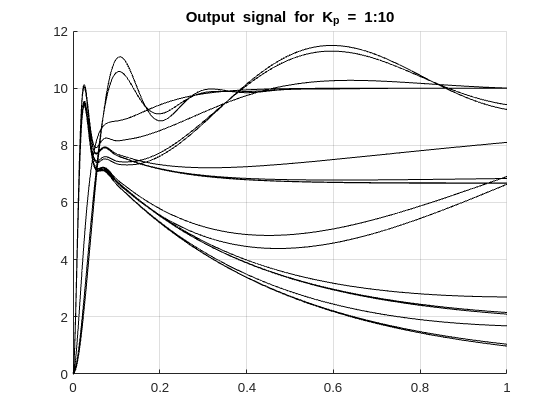

figure;
hold on;
title("Output signal for K_p = 1:10");
for i = out
    info = stepinfo(i.yout, i.tout, 10);
    if(info.Overshoot > 15 || isnan(info.SettlingTime))
        continue;
    end
    plot(i.tout, i.yout, "Color","black");
end
hold off;
grid on;